# Landscape

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
f(X) = \min_{Q} f(X,Q) = f\bigg(\frac{1}{k}\sum_j^k Y_jQ_j, Q\bigg) =f(\chi(Q),Q)
\\
\nabla f(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), \big(Y_j^\top(Y_jQ_j-X)\big)_j\bigg)
\\
\nabla^2 f(X,Q)[U,V] = \nabla f(U,V)$$


## Dependance to the initialization

clear
n=32; % data dimension
rr=round(logspace(0,log10(n),7)); % size of factorization Y of data A (chose <8 if n=32)
pp=rr; % size of factorization X of barycenter B
k=100; % number of matrices
Nrepeat=10;

mybar = waitbar(0,"Initialization");
Brelative_std = NaN(length(rr));
niter = NaN(length(rr));
options.verbosity=0;

for jr=1:length(rr)
    r=rr(jr);
    for jp=jr:length(pp)
        p=pp(jp);

        A = data(n,k,r);
        prob = nonconvex_problem(A,r,p);
        X = zeros(n,p,Nrepeat);
        niter(jr,jp)=0;

        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",r,p,n,j,Nrepeat))
            [x,~,info] = trustregions(prob,[],options);
            X(:,:,j) = x.X;
            niter(jr,jp) = niter(jr,jp) + info(end).iter;
        end
        
        niter(jr,jp) = niter(jr,jp) / Nrepeat;
        BB = pagemtimes(X, multitransp(X));
        Bmean = sum(BB,3)/Nrepeat;
        Bstd = norm(Bmean-BB,"fro")/(Nrepeat-1);
        Brelative_std(jr,jp) = Bstd/norm(Bmean,"fro");
    end
end
close(mybar)
%save("data/consitency_rp.mat","Brelative_std","niter")

load("data/consitency_rp.mat")
heatmap(pp,rr,Brelative_std)
title(sprintf("Relative STD \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")

Unrecognized function or variable
'pp'.

%exportgraphics(gcf,"graphics/landscape_relative_std.pdf")
heatmap(pp,rr,niter)
title(sprintf("Number of iterations \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
%exportgraphics(gcf,"graphics/landscape_iterations.pdf")

## Convergence to cvx solution

Whishart Z*Z' model, with true barycenter by CVX

clear
n=10; % data dimension
rr=1:1:5; % size of factorization Y of data A (chose <8 if n=32)
pp=rr; % size of factorization X of barycenter B
k=10; % number of matrices
Nrepeat=5;

mybar = waitbar(0,"Initialization");
Berr = NaN(length(rr),length(pp),Nrepeat);
costerr = NaN(length(rr),length(pp),Nrepeat);
options.verbosity=0;

for jr=1:length(rr)
    for jp=1:length(pp)
        if pp(jp) < rr(jr) % invalid (must r <= p)
            continue
        end
        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",rr(jr),pp(jp),n,j,Nrepeat))

            A = data(n,k,rr(jr)); % data
            [Bcvx,cost_cvx,info_cvx] = cvx_solve(A); % compute true barycenter by cvx
            prob = nonconvex_problem2(A,rr(jr),pp(jp)); % nonconvex problem, CHANGE TO VERSION 2
            [Q,cost,info] = trustregions(prob,[],options); % solve
            B = prob.B(Q);
            Berr(jr,jp,j) = norm(Bcvx-B,"fro")/norm(Bcvx,"fro");
            costerr(jr,jp,j) = (cost - cost_cvx) / cost_cvx;
            niter(jr,jp,j) = info(end).iter;
        end
    end
end
close(mybar)
%save("data/convergence2cvx.mat")

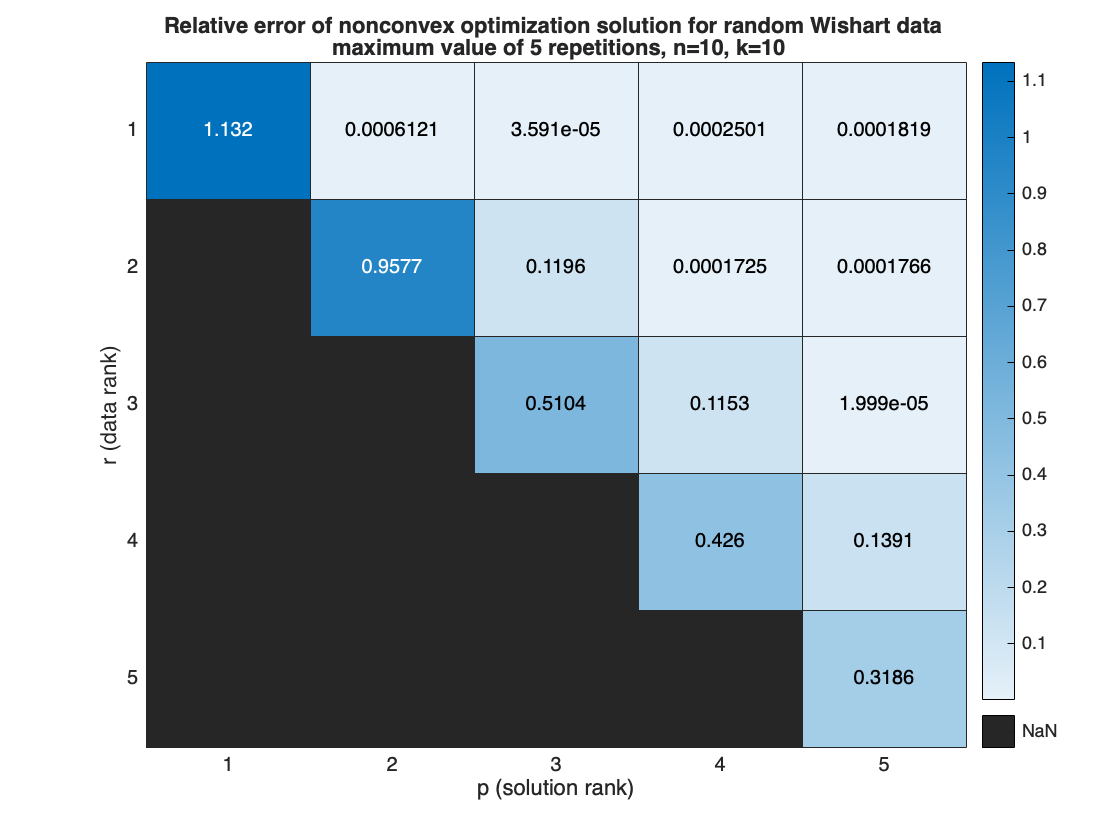

load("data/convergence2cvx.mat")
heatmap(pp,rr,max(Berr,[],3))
title(sprintf("Relative error of nonconvex optimization solution for random Wishart data \n maximum value of %d repetitions, n=%d, k=%d",Nrepeat,n,k))
xlabel("p (solution rank)")
ylabel("r (data rank)")
exportgraphics(gcf,"graphics/convergence2cvx.pdf")
heatmap(pp,rr,min(costerr,[],3))
title(sprintf("Relative cost error of nonconvex optimization for random Wishart data \n maximum of %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")

ylabel("r")
exportgraphics(gcf,"graphics/convergence2cvx_costerr.pdf")

## Fixed equation

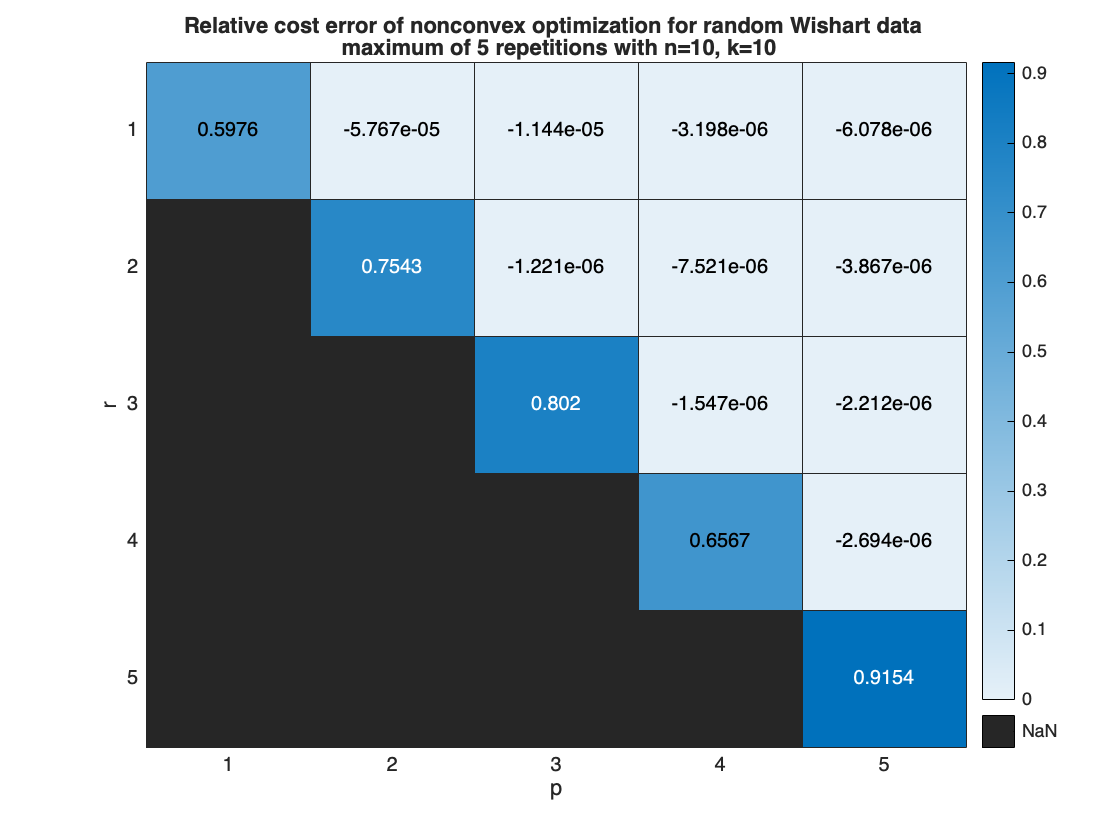

clear
n=5; % data matrix dimension
kk=2:5; % number of data samples

rr=1:5; % rank of data
Nrepeat=10;
for ik=1:length(kk)
    fprintf("%d,",kk(ik))
    for ir=1:length(rr)
        for rep=1:Nrepeat
            A = data(n,kk(ik),rr(ir));
            prob = convex_problem(A);
            [B, cost, info] = cvx_solve(A);
            err(ik,ir,rep) = norm(prob.fixed_equation(B)-B,"fro") / norm(B,"fro");
        end
    end
end
%save("data/fixed_equation.mat")
max(err,[],"all")

2,3,4,5,

## Convergence to true barycenter

CBC Model

clear

ans = 4.7732e-04

n=100; % data dimension
rr=1:1:10; % size of factorization Y of data A
pp=rr; % size of factorization X of barycenter B
k=10; % number of matrices
Nrepeat=5;

mybar = waitbar(0,"Initialization");
Berr = NaN(length(rr),length(pp),Nrepeat);
costerr = NaN(length(rr),length(pp),Nrepeat);
options.verbosity=0;

for jr=1:length(rr)
    for jp=1:length(pp)
        if pp(jp) < rr(jr) % invalid
            continue
        end
        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",rr(jr),pp(jp),n,j,Nrepeat))

            Btrue = data(n,1,rr(jr)); % arbitrary target barycenter
            A = data_scaled(Btrue,k,"exact"); % data
            prob = nonconvex_problem2(A,rr(jr),pp(jp)); % problem
            [Q,cost,info] = trustregions(prob,[],options); % solve
            B = prob.B(Q);
            Berr(jr,jp,j) = norm(Btrue-B,"fro")/norm(Btrue,"fro");
            costerr(jr,jp,j) = (cost - cost_variance(A,Btrue))/cost_variance(A,Btrue);
            niter(jr,jp,j) = info(end).iter;
        end
    end
end
close(mybar)
save("data/convergence2Btrue.mat")

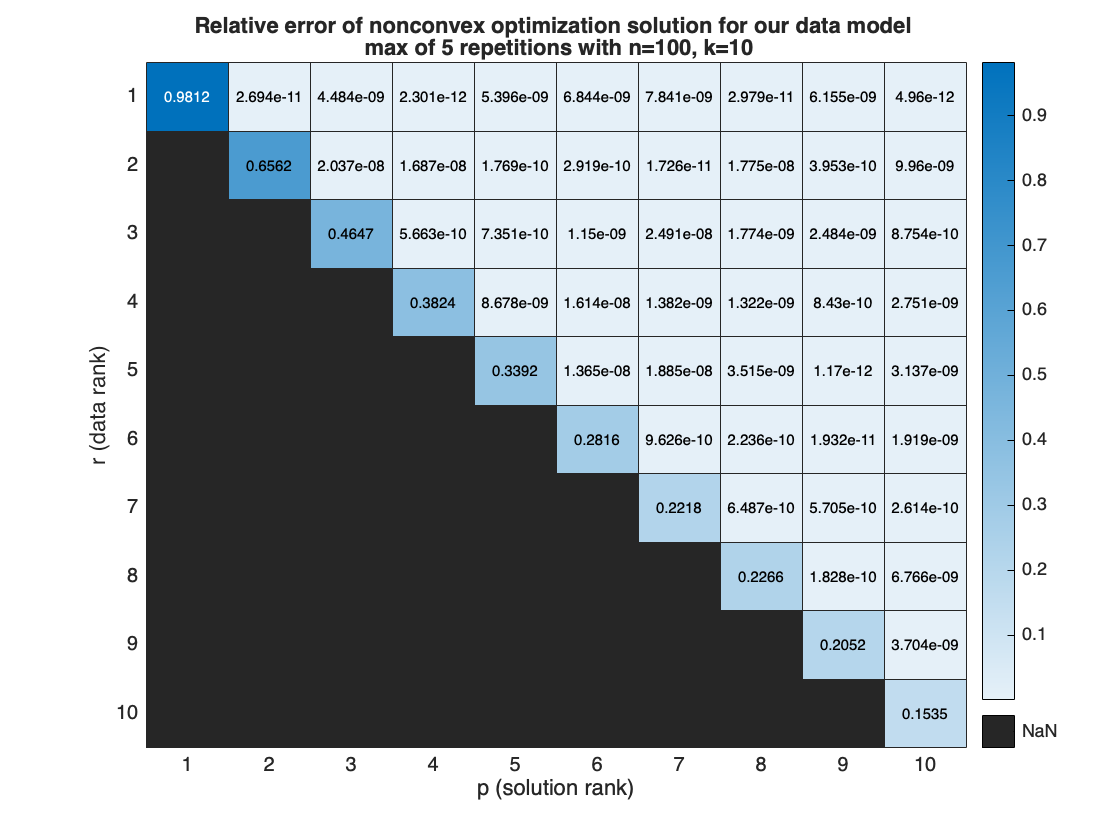

load("data/convergence2Btrue.mat")
heatmap(pp,rr,max(Berr,[],3))
title(sprintf("Relative error of nonconvex optimization solution for our data model \n max of %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p (solution rank)")
ylabel("r (data rank)")
exportgraphics(gcf,"graphics/convergence2Btrue_Berr.pdf")
disp([median(Berr(1,1,:)), median(Berr(2,2,:))])
heatmap(pp,rr,max(costerr,[],3))
title(sprintf("Relative cost error of nonconvex optimization for our data model \n min of %d repetitions with n=%d, k=%d",Nrepeat,n,k))

xlabel("p (solution rank)")

    0.7264    0.5799



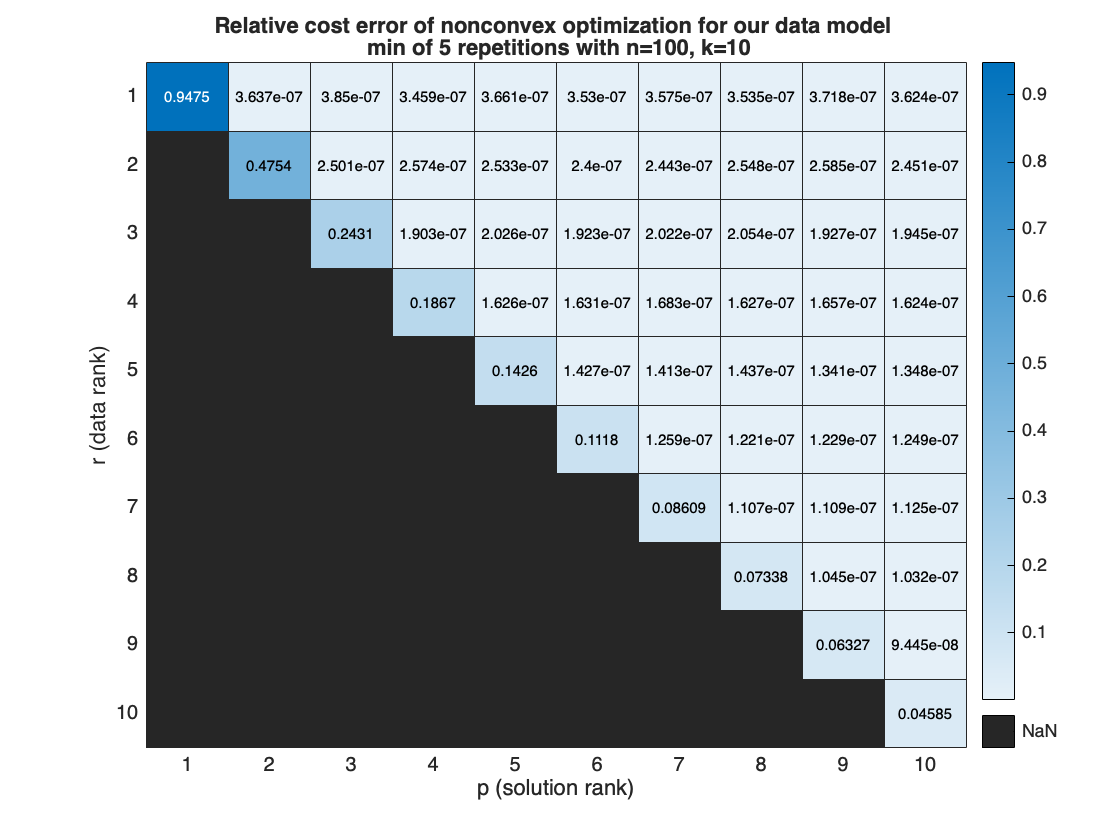

ylabel("r (data rank)")
exportgraphics(gcf,"graphics/convergence2Btrue_costerr.pdf")
proba = 0.5^k % probability for orthogonal matrices initialization of being in the right connected component.
sum(Berr(5,5,:)<1e-3)

## Rank of solutions

clear
n=10; % data dimension

proba = 9.7656e-04

kk=2:1:5; % number of matrices

ans = 0

rr=1:1:5;
Nrepeat=10;
eigenvalues= zeros(length(kk),length(rr),n,Nrepeat);
for jk=1:length(kk)
    k=kk(jk);
    fprintf("%d,",k);
    for jr=1:length(rr)
        r=rr(jr);
        for j=1:Nrepeat
            %[k,r,j]
            A = data(n,k,r);
            [B,Bcost,info] = cvx_solve(A);
            eigenvalues(jk,jr,:,j)=sort(abs(eig(B)),"descend");
            ranks(jk,jr,j) = rank(B,1e-4);
        end
    end
end
save("data/rank.mat")

%load("data/rank.mat")

2,

3,4,5,

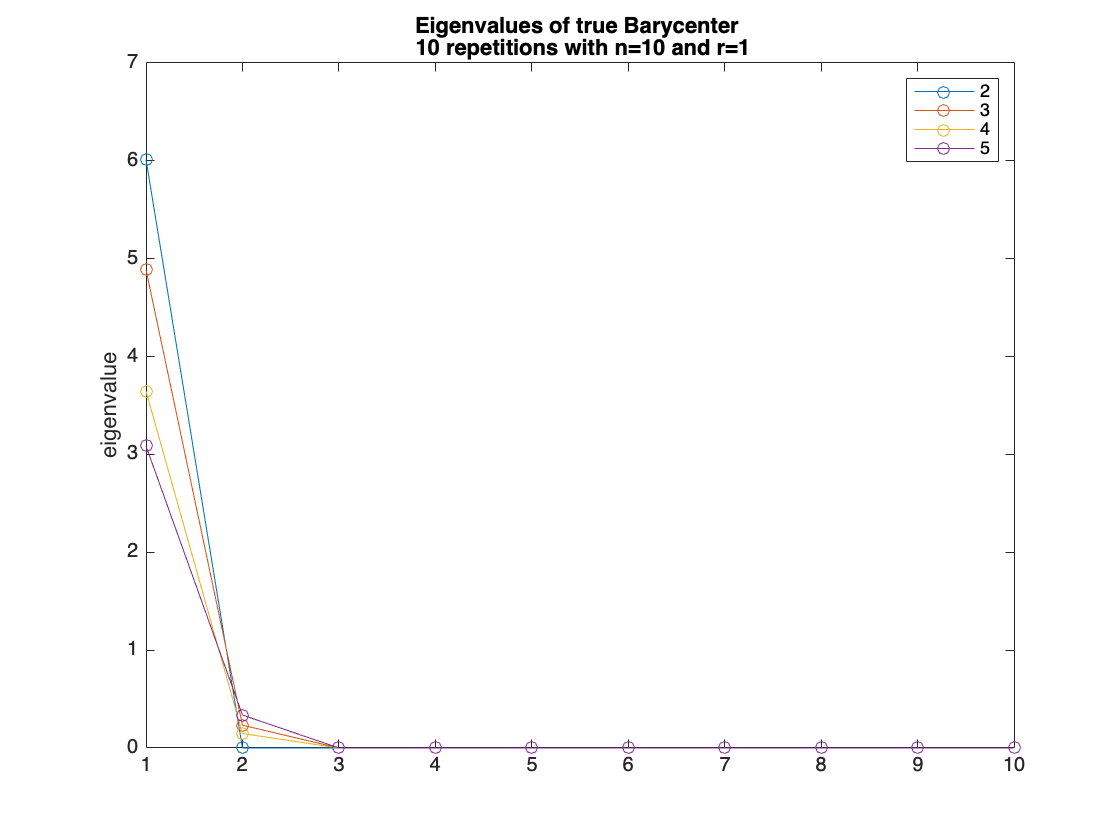

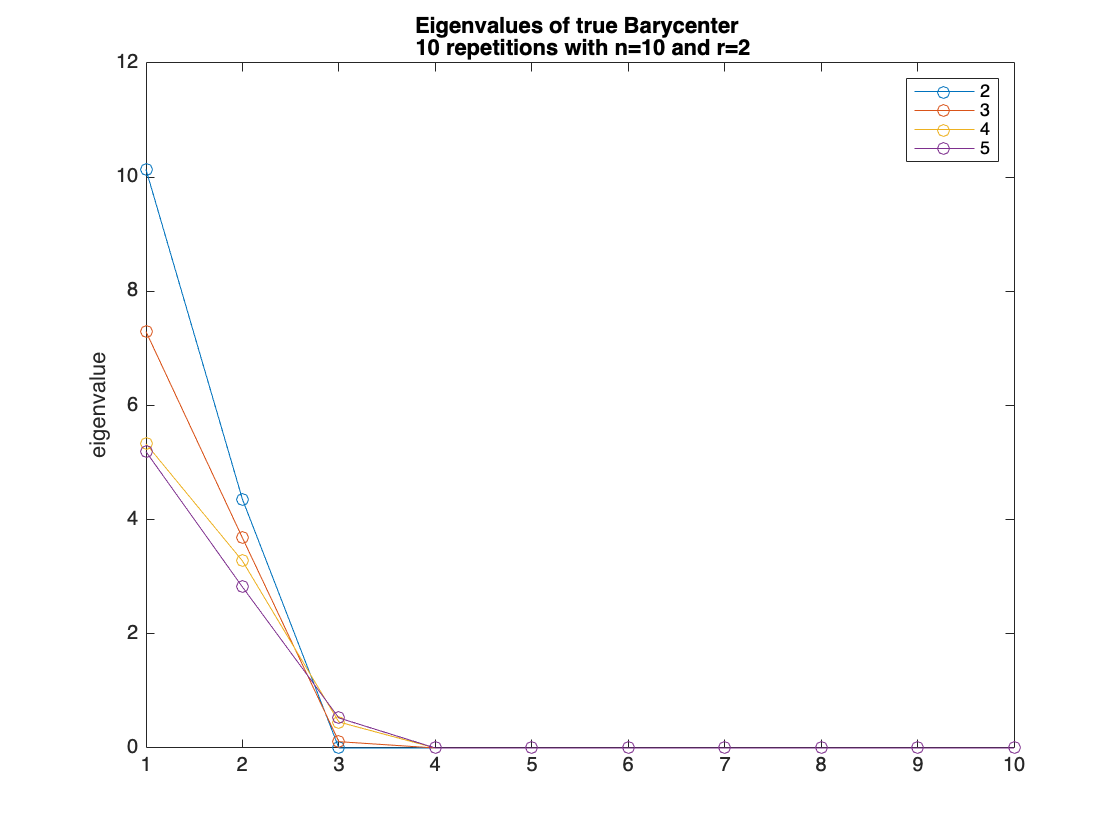

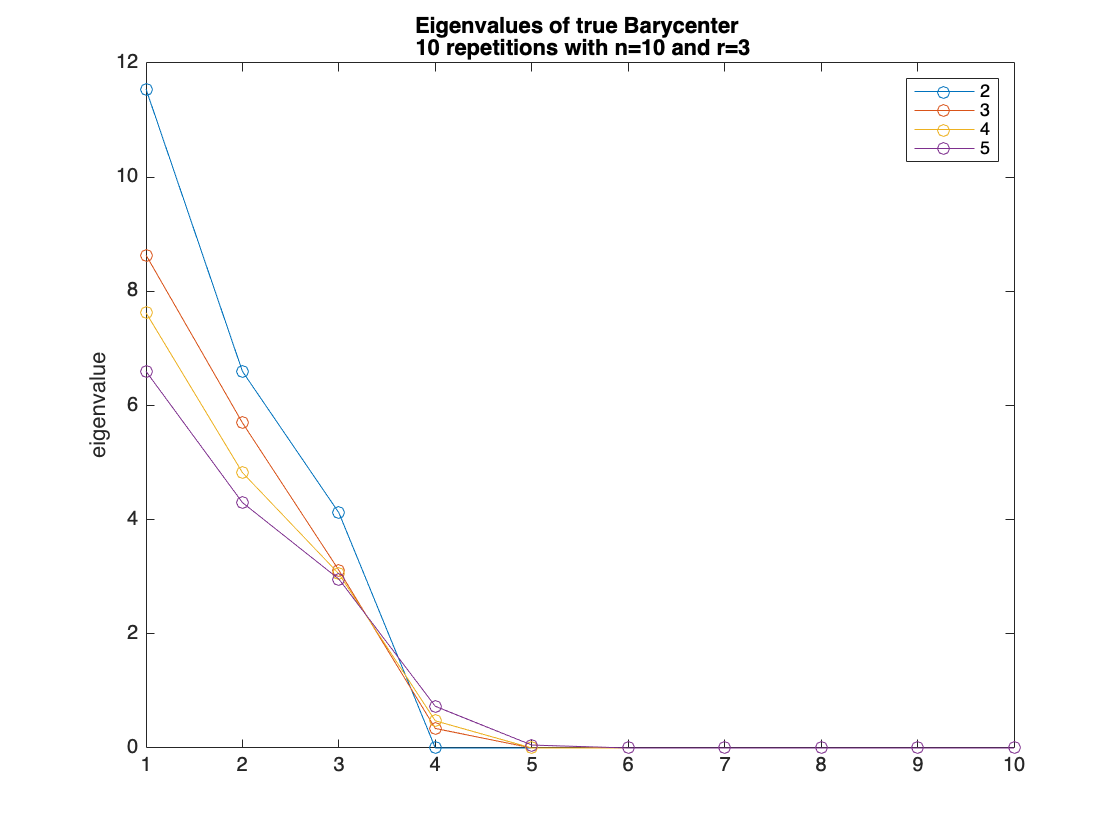

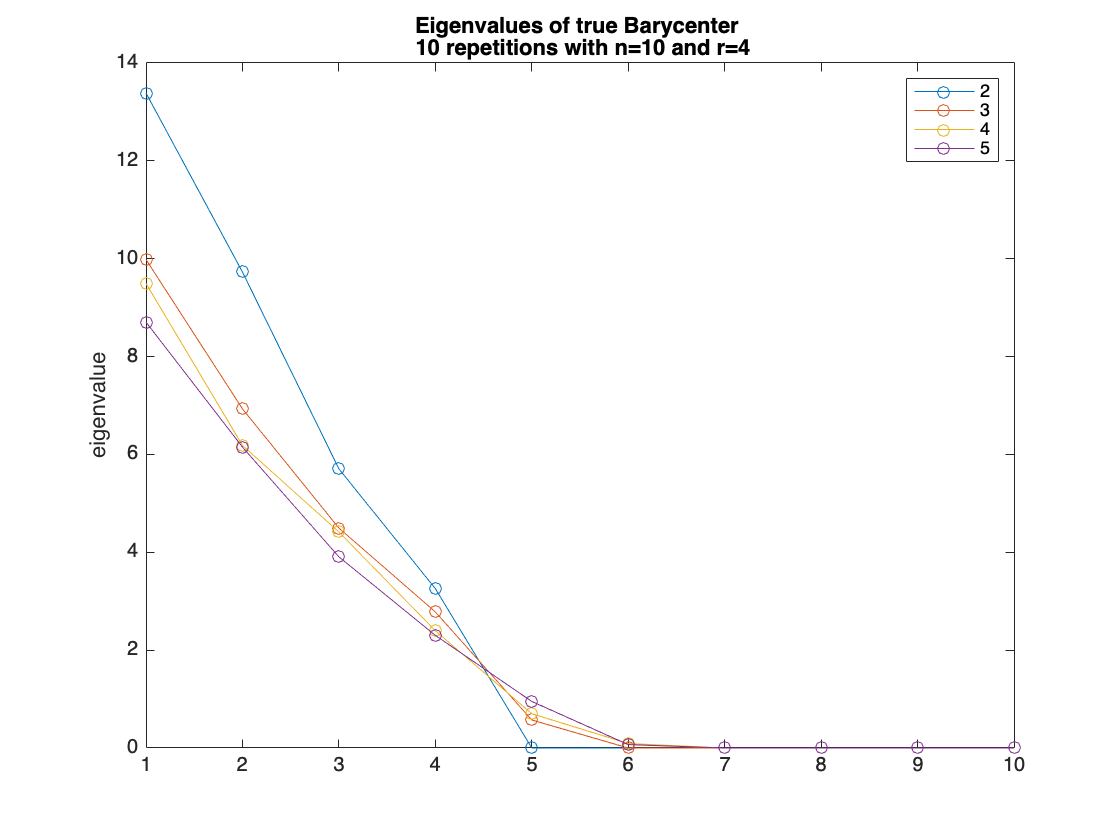

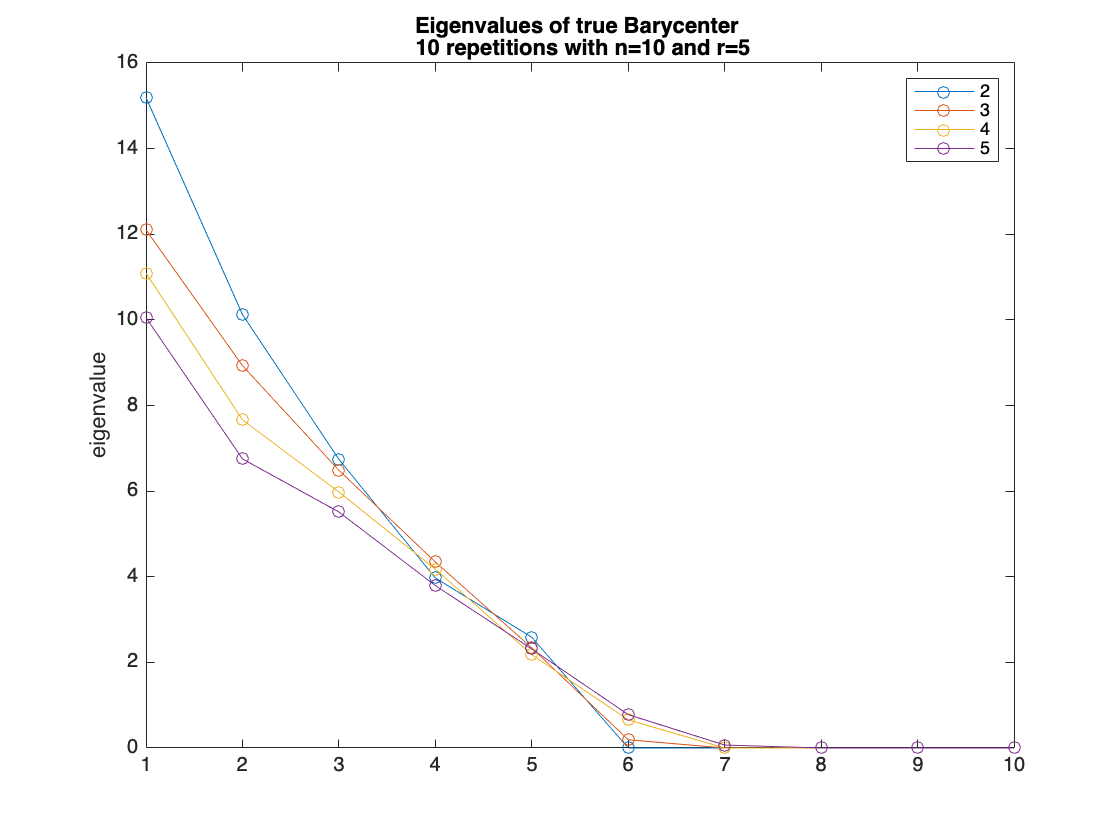

for jr=1:length(rr)
    eig_mean = mean(eigenvalues(:,jr,:,:),4);
    figure()
    plot(squeeze(eig_mean)',"o-")
    title(sprintf("Eigenvalues of true Barycenter \n %d repetitions with n=%d and r=%d",Nrepeat,n,rr(jr)))
    ylabel("eigenvalue")
    legend(string(kk))
    exportgraphics(gcf,sprintf("graphics/rank_r%d.pdf",rr(jr)))
end

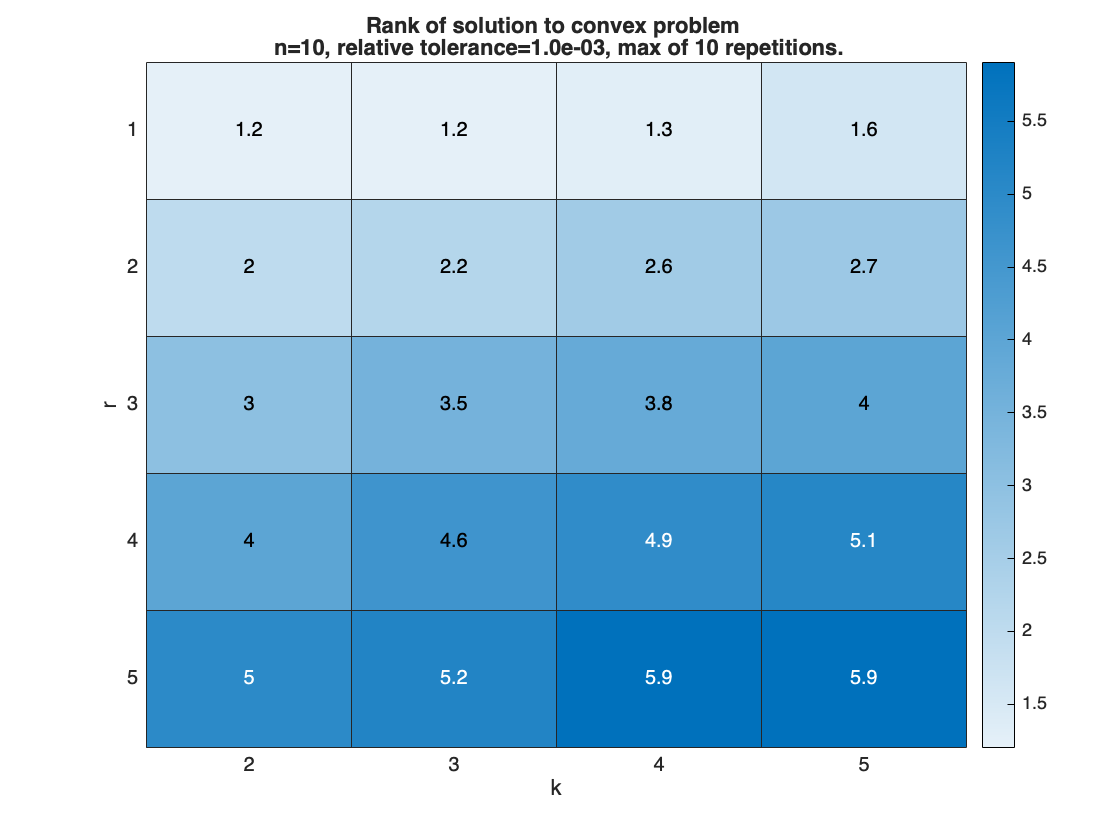

%load("data/rank.mat")
relat_tol=1e-3;
ranks=mean(ranks,3);
heatmap(kk,rr,ranks')
xlabel("k")
ylabel("r")
title(sprintf("Rank of solution to convex problem \n n=%d, relative tolerance=%.1e, max of %d repetitions.",n,relat_tol,Nrepeat))
exportgraphics(gcf,"graphics/ranks_rp.pdf")

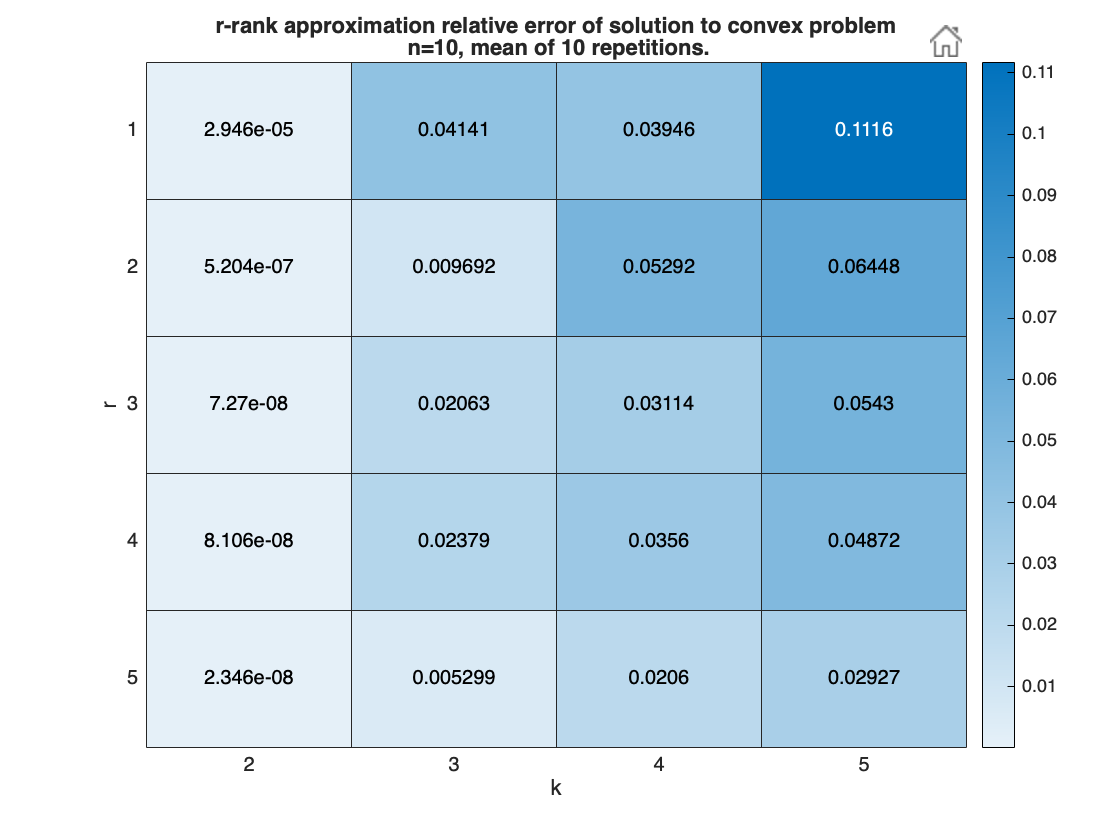

for jr=1:length(rr)
    same_rank(:,jr) = mean(sum(eigenvalues(:,jr,rr(jr)+1:end,:),3)./sum(eigenvalues(:,jr,:,:),3),4);
end
heatmap(kk,rr,same_rank')
xlabel("k")
ylabel("r")
title(sprintf(" r-rank approximation relative error of solution to convex problem \n n=%d, mean of %d repetitions.",n,Nrepeat))
exportgraphics(gcf,"graphics/same_ranks_rp.pdf")

## Matrix recovery

clear
n=5;
r_x=1;
r_S=5;
k=r_S*n;
Nrepeat=5;

Nrepeat = 5

for rep=1:Nrepeat
    S=data(n,1,r_S);
    x=randn(n,r_x,k);
    prob=matrix_recovery(S,x);
    options.verbosity=0;
    [Q,cost,info] = trustregions(prob.nonconvex_problem,[],options);
    B = prob.nonconvex_problem.B(Q);
    Sbis = prob.Csqrtinv * B * prob.Csqrtinv;
    err(rep)=norm(S-Sbis,"fro")/norm(S,"fro");
end
max(err)

ans = 4.3613e-07